# Assignment #3

Connor Cavarretta

ECE 651

10/12/2025

## Question 4.48

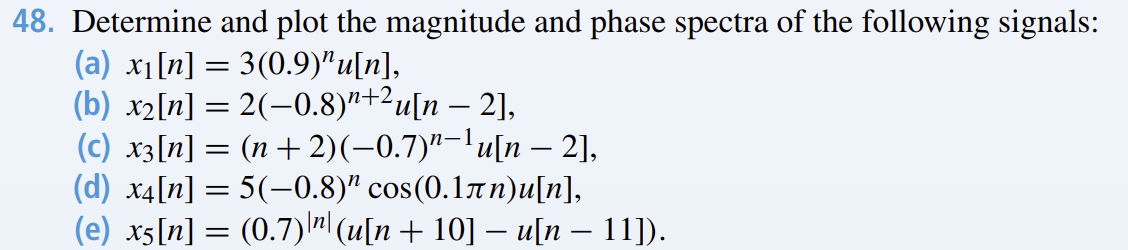

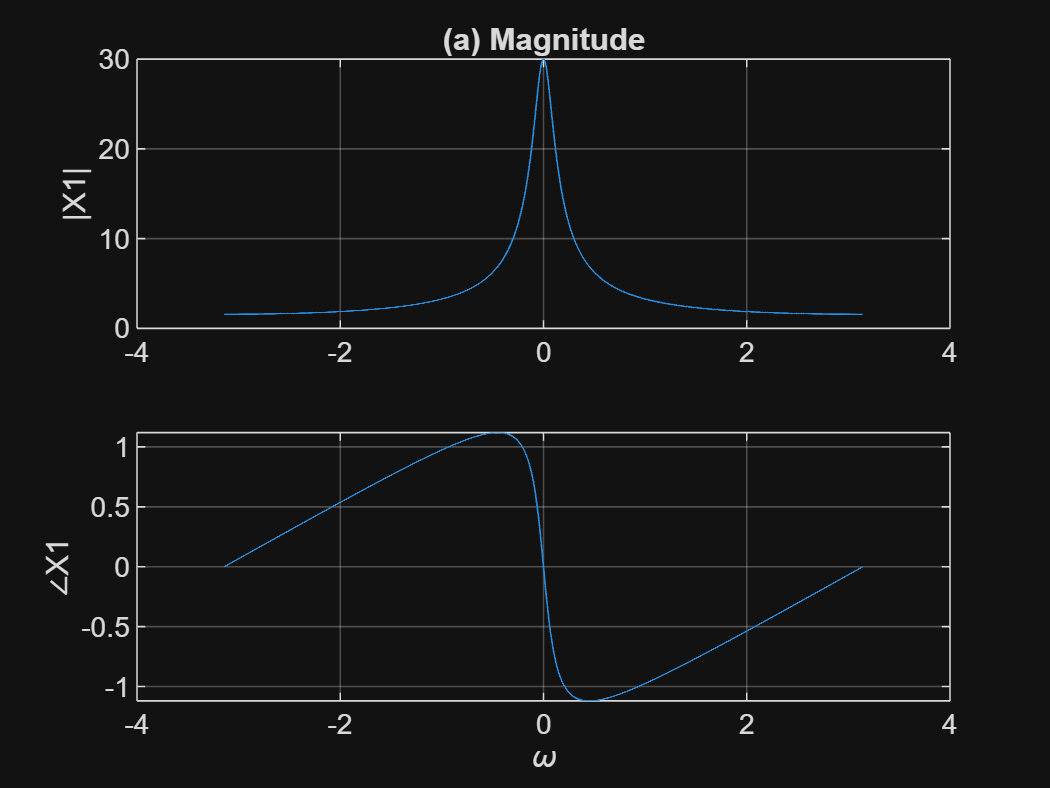

% Frequency grid
w = linspace(-pi,pi,4096); jw = 1i*w;

%% (a) x1[n] = 3(0.9)^n u[n]
X1 = 3 ./ (1 - 0.9*exp(-1i*w));

%% (b) x2[n] = 2(-0.8)^{n+2} u[n-2]
X2 = 2*( (-0.8)^4 ) .* exp(-1i*2*w) ./ (1 - (-0.8)*exp(-1i*w));

%% (c) x3[n] = (n+2)(-0.7)^{n-1} u[n-2]
r  = -0.7*exp(-1i*w);
X3 = exp(-1i*2*w) .* (-0.7) .* ( r./(1-r).^2 + 4./(1-r) );

%% (d) x4[n] = 5(-0.8)^n cos(0.1π n) u[n]
Om = 0.1*pi;
X4 = 2.5*( 1./(1 - (-0.8)*exp(-1i*(w-Om))) + 1./(1 - (-0.8)*exp(-1i*(w+Om))) );

%% (e) x5[n] = (0.7)^{|n|}(u[n+10]-u[n-11])  (finite length)
n  = -10:10;
x5 = (0.7).^abs(n);
X5 = x5 * exp(-1i*(n.'*w));   % sum_{n=-10}^{10} x5[n] e^{-jwn}

%% Plot results
figure;
subplot(2,1,1), plot(w, abs(X1)), grid on, title('(a) Magnitude'), ylabel('|X1|')
subplot(2,1,2), plot(w, angle(X1)), grid on, ylabel('∠X1'), xlabel('\omega')

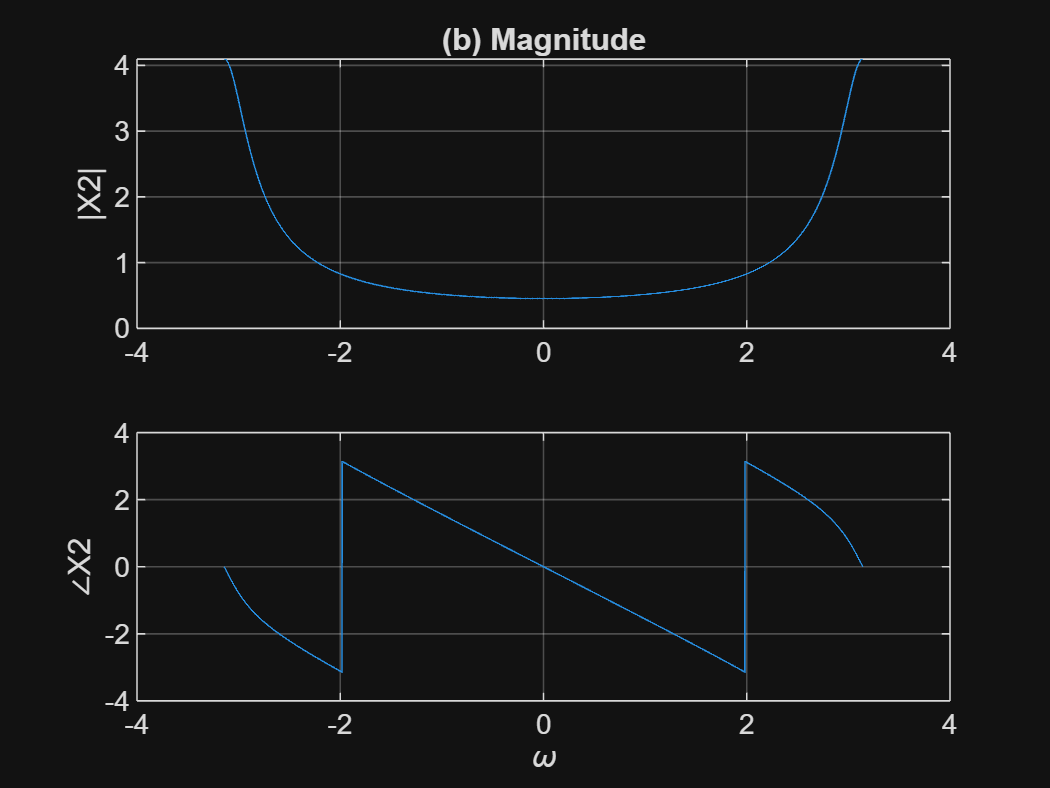

figure;
subplot(2,1,1), plot(w, abs(X2)), grid on, title('(b) Magnitude'), ylabel('|X2|')
subplot(2,1,2), plot(w, angle(X2)), grid on, ylabel('∠X2'), xlabel('\omega')

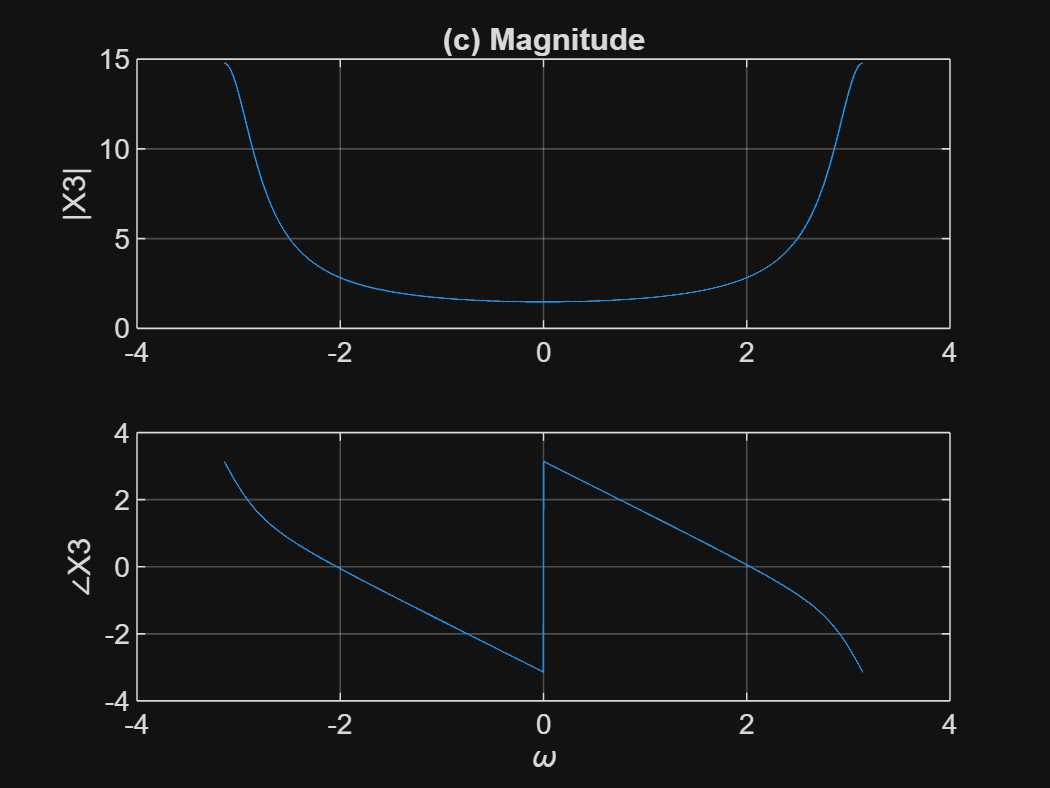

figure;
subplot(2,1,1), plot(w, abs(X3)), grid on, title('(c) Magnitude'), ylabel('|X3|')
subplot(2,1,2), plot(w, angle(X3)), grid on, ylabel('∠X3'), xlabel('\omega')

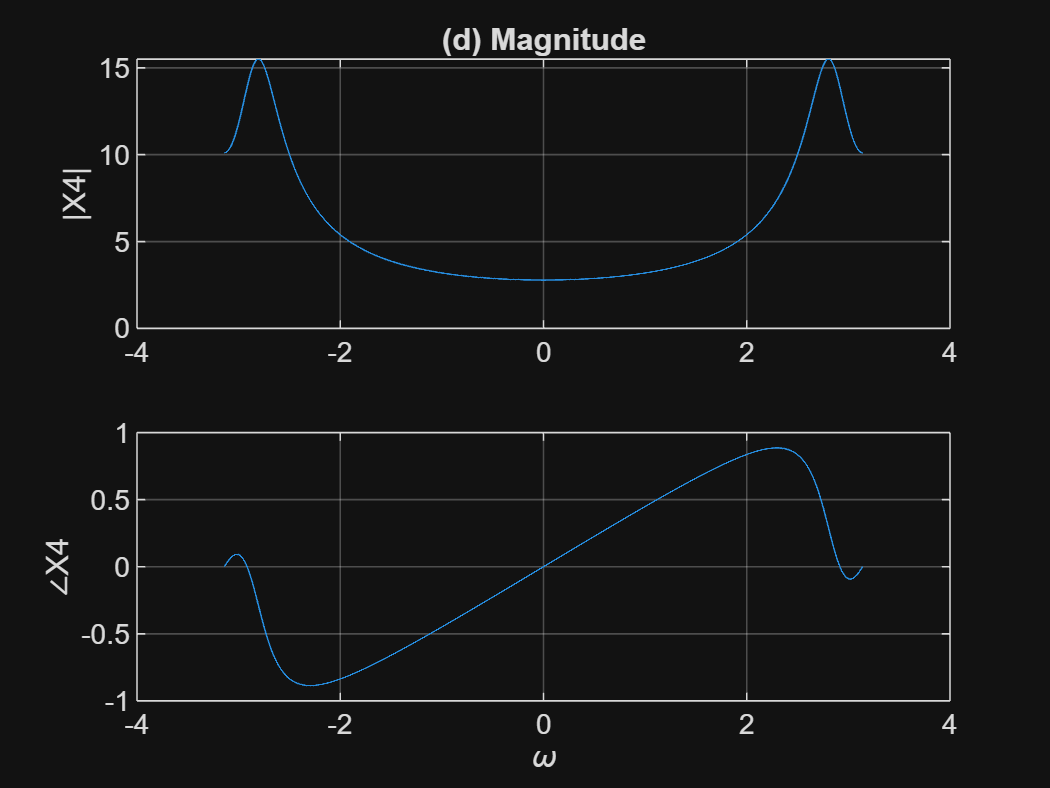

figure;
subplot(2,1,1), plot(w, abs(X4)), grid on, title('(d) Magnitude'), ylabel('|X4|')
subplot(2,1,2), plot(w, angle(X4)), grid on, ylabel('∠X4'), xlabel('\omega')

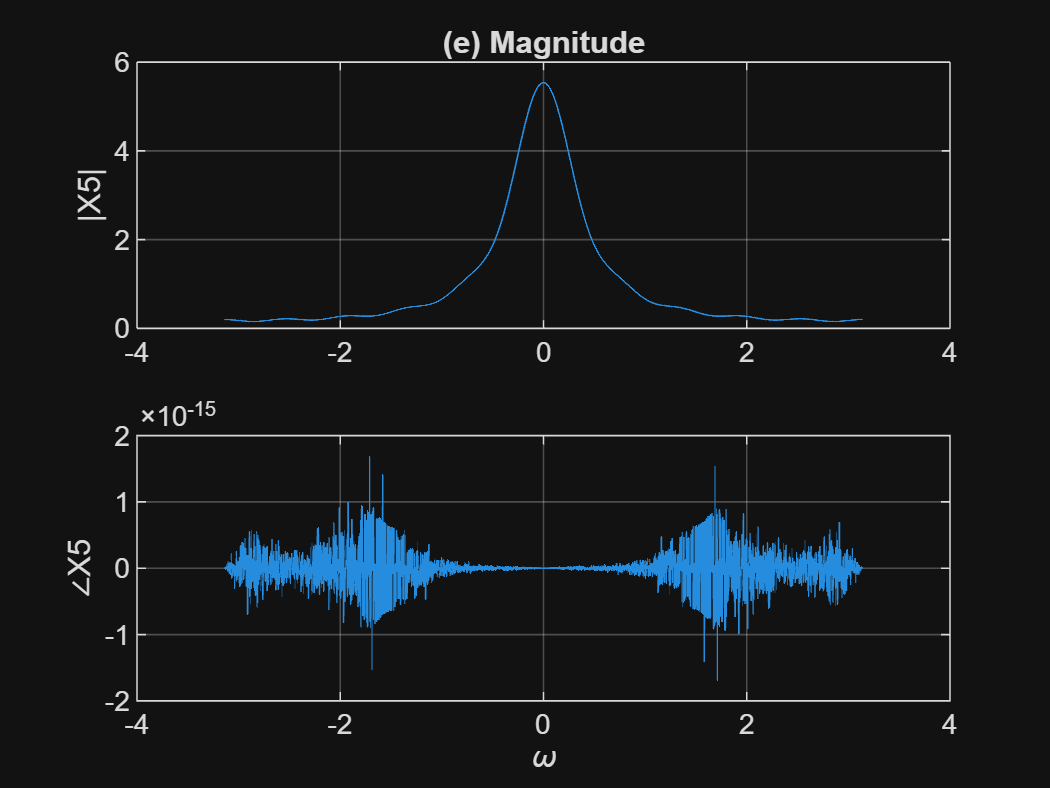

figure;
subplot(2,1,1), plot(w, abs(X5)), grid on, title('(e) Magnitude'), ylabel('|X5|')
subplot(2,1,2), plot(w, angle(X5)), grid on, ylabel('∠X5'), xlabel('\omega')

## Question 4.49

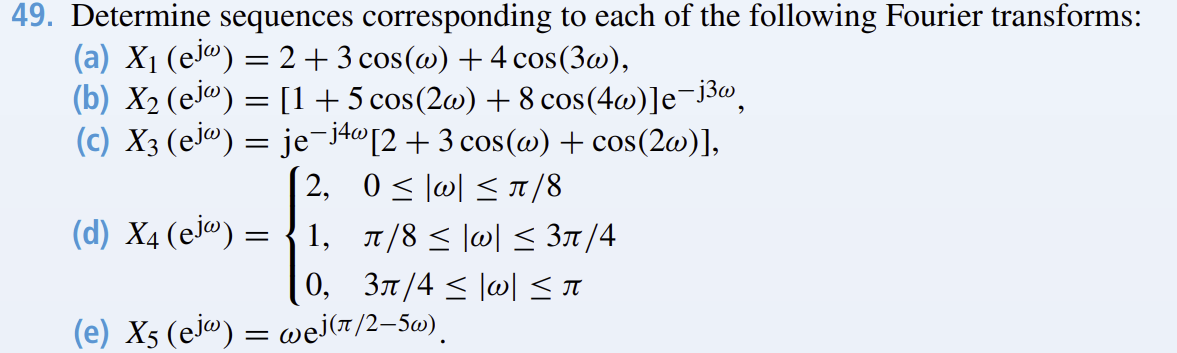

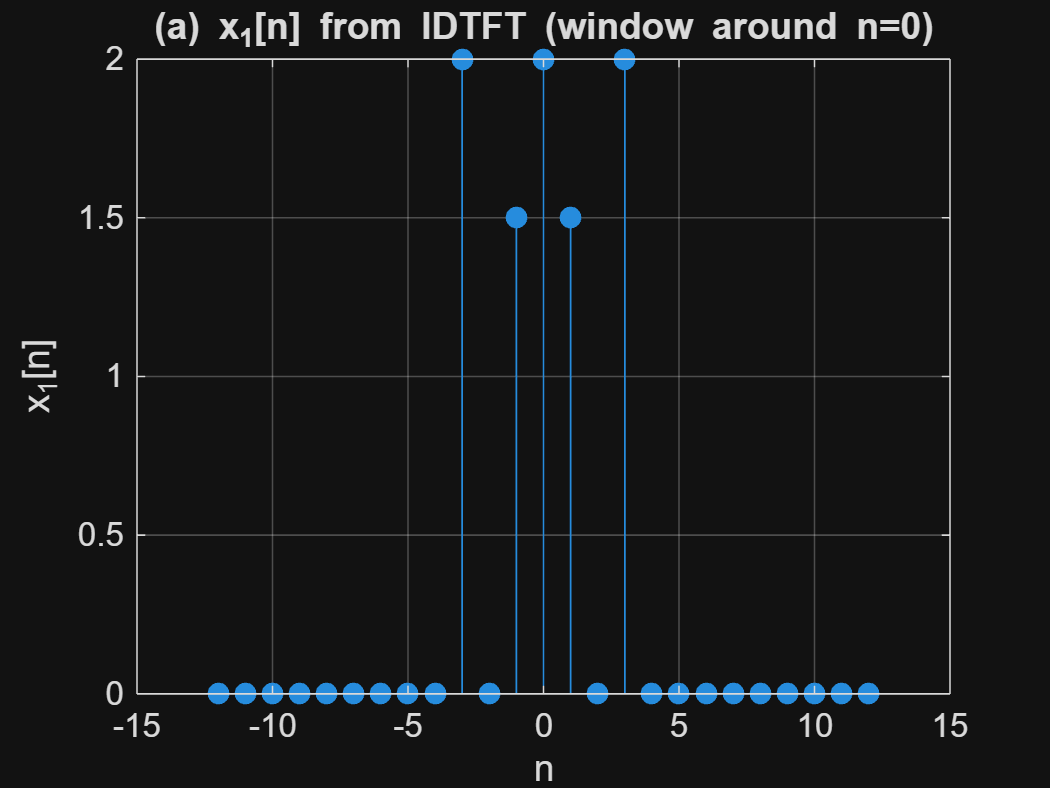

N  = 2048;                      % frequency/time grid size
M  = 12;                        % show n in [-M, M]
w  = linspace(-pi,pi,N+1); w(end) = [];

% Helper to grab a symmetric n-window around 0 from a length-N sequence
getwin = @(x) x(mod((-M:M), N)+1);     % n=-M:1:M  -> indices 1..N

%% (a) X1(e^{jw}) = 2 + 3 cos(w) + 4 cos(3w)
X1 = 2 + 3*cos(w) + 4*cos(3*w);
x1 = ifft(ifftshift(X1));
figure; stem(-M:M, real(getwin(x1)),'filled'); grid on
title('(a) x_1[n] from IDTFT (window around n=0)'); xlabel('n'); ylabel('x_1[n]')

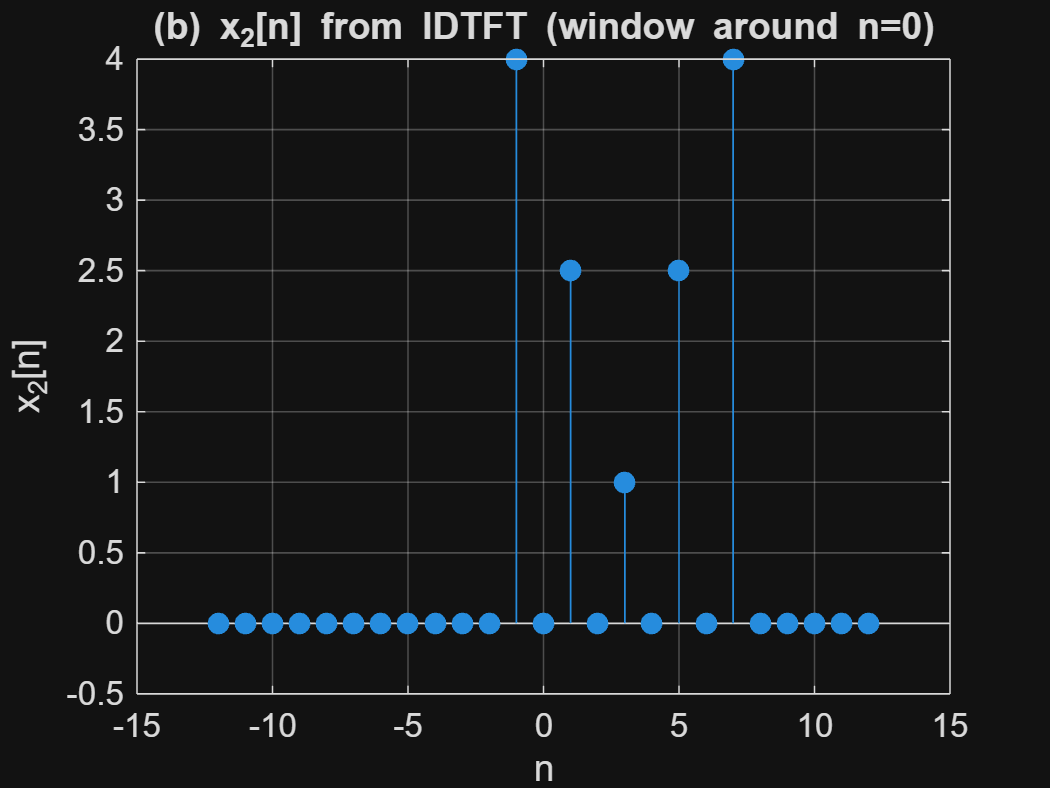


%% (b) X2(e^{jw}) = [1 + 5 cos(2w) + 8 cos(4w)] e^{-j 3 w}
X2 = (1 + 5*cos(2*w) + 8*cos(4*w)) .* exp(-1i*3*w);
x2 = ifft(ifftshift(X2));
figure; stem(-M:M, real(getwin(x2)),'filled'); grid on
title('(b) x_2[n] from IDTFT (window around n=0)'); xlabel('n'); ylabel('x_2[n]')

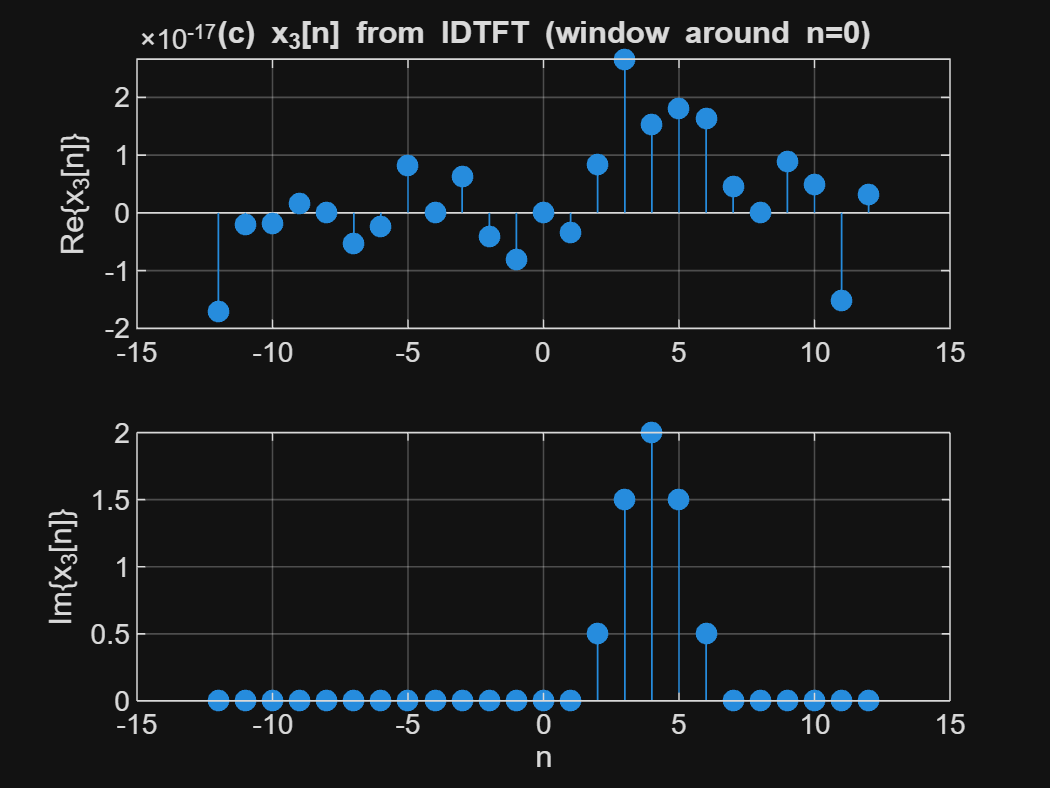


%% (c) X3(e^{jw}) = j e^{-j4w} [2 + 3 cos(w) + cos(2w)]
X3 = 1i * exp(-1i*4*w) .* (2 + 3*cos(w) + cos(2*w));
x3 = ifft(ifftshift(X3));
figure; 
subplot(2,1,1); stem(-M:M, real(getwin(x3)),'filled'); grid on
ylabel('Re\{x_3[n]\}'); title('(c) x_3[n] from IDTFT (window around n=0)')
subplot(2,1,2); stem(-M:M, imag(getwin(x3)),'filled'); grid on
xlabel('n'); ylabel('Im\{x_3[n]\}')

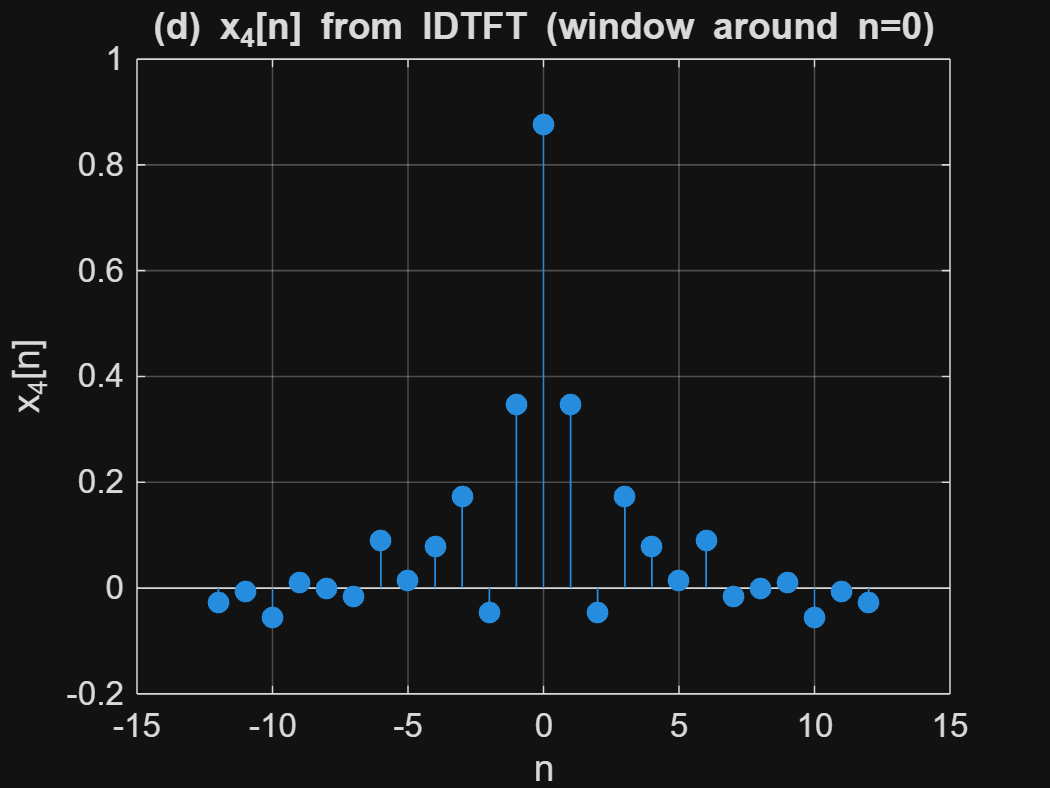


%% (d) X4(e^{jw}) = piecewise: 2 on |w|<=pi/8; 1 on pi/8<|w|<=3pi/4; 0 otherwise
absw = abs(w);
X4 = 2*(absw<=pi/8) + 1*(absw>pi/8 & absw<=3*pi/4);
x4 = ifft(ifftshift(X4));
figure; stem(-M:M, real(getwin(x4)),'filled'); grid on
title('(d) x_4[n] from IDTFT (window around n=0)'); xlabel('n'); ylabel('x_4[n]')

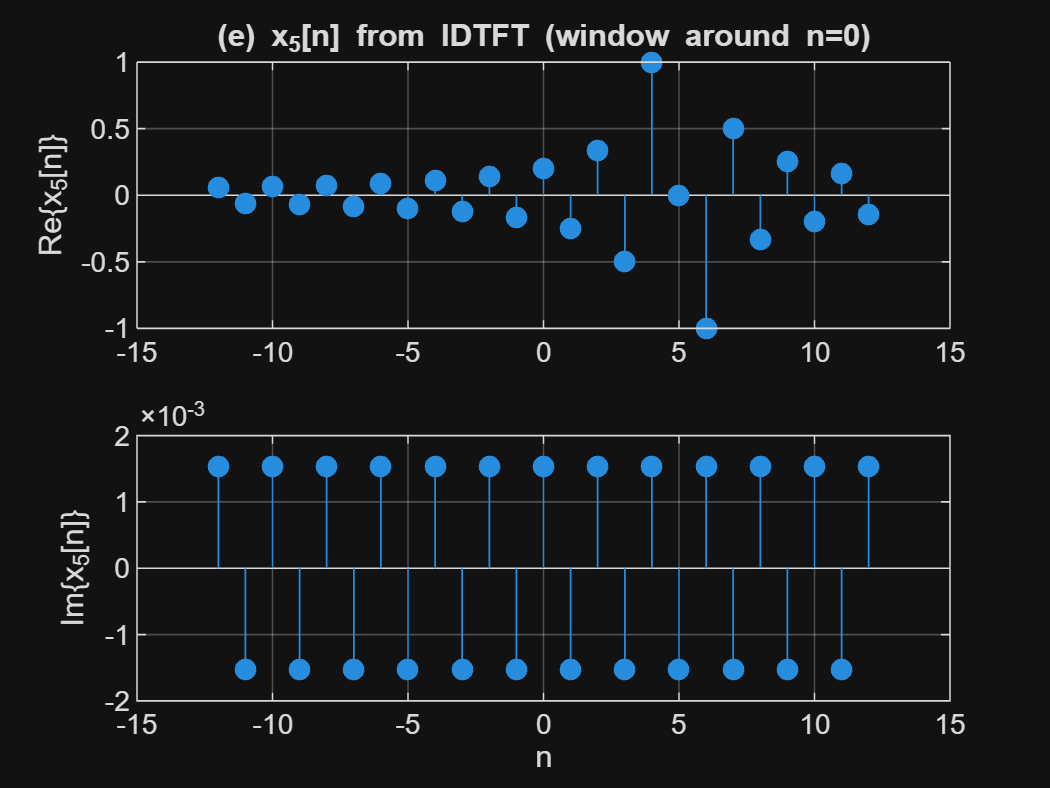


%% (e) X5(e^{jw}) = w * e^{j(\pi/2 - 5w)} = j w e^{-j5w}
X5 = 1i*w .* exp(-1i*5*w);
x5 = ifft(ifftshift(X5));
figure; 
subplot(2,1,1); stem(-M:M, real(getwin(x5)),'filled'); grid on
ylabel('Re\{x_5[n]\}'); title('(e) x_5[n] from IDTFT (window around n=0)')
subplot(2,1,2); stem(-M:M, imag(getwin(x5)),'filled'); grid on
xlabel('n'); ylabel('Im\{x_5[n]\}')

## Question 5.13

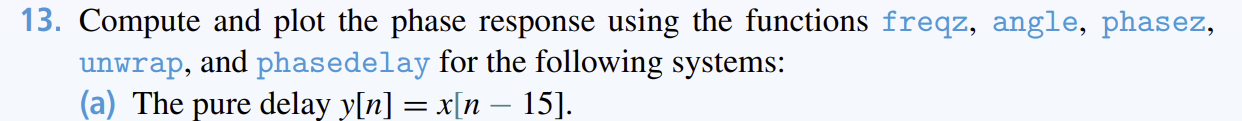

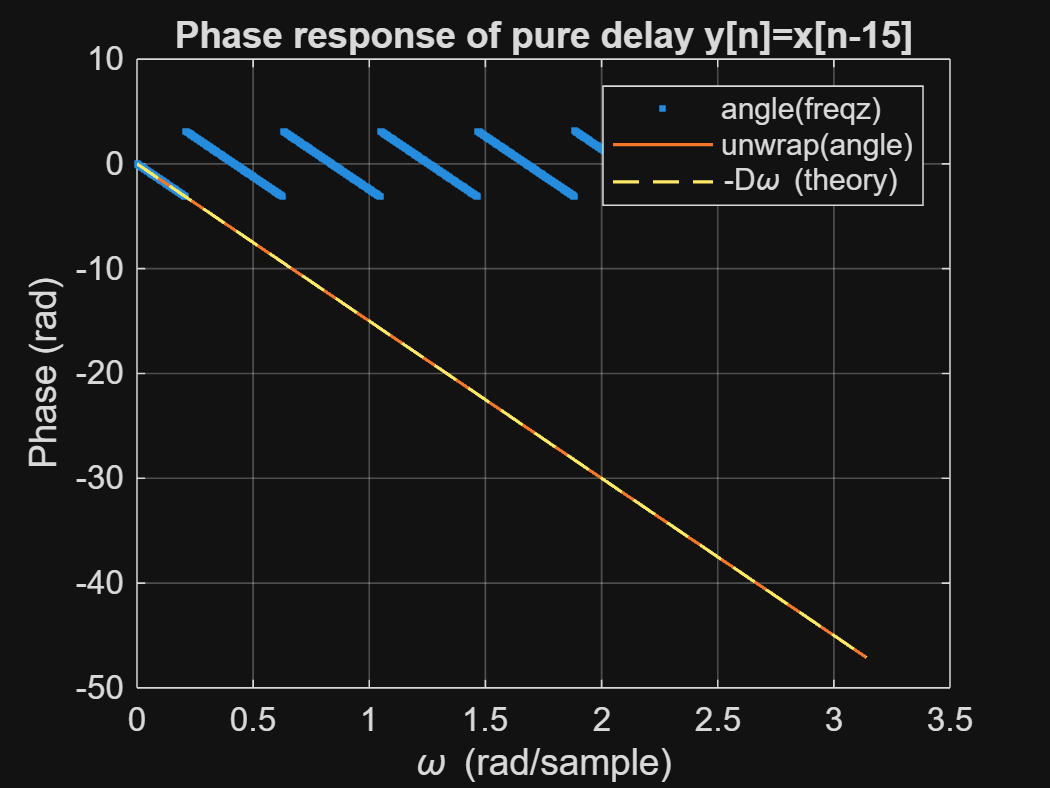

D = 15;
b = [zeros(1,D) 1];  % FIR: z^{-15}
a = 1;

% Frequency response
[H,w] = freqz(b,a,2048);       % w in [0,pi]
phi_wrap = angle(H);
phi_unwrap = unwrap(phi_wrap);

% Built-in phase and phase delay
[phi_phasez, w_pz] = phasez(b,a,2048);
[tau_pd, w_pd]     = phasedelay(b,a,2048);

% Theoretical
phi_true = -D*w;
tau_true = D*ones(size(w)); tau_true(1) = NaN; % avoid 0/0 at w=0

% Phase (wrapped vs unwrapped vs theory)
figure;
plot(w, phi_wrap, '.', w, phi_unwrap, '-', w, phi_true, '--','LineWidth',1); grid on
xlabel('\omega (rad/sample)'); ylabel('Phase (rad)')
legend('angle(freqz)','unwrap(angle)','-D\omega (theory)')
title('Phase response of pure delay y[n]=x[n-15]')

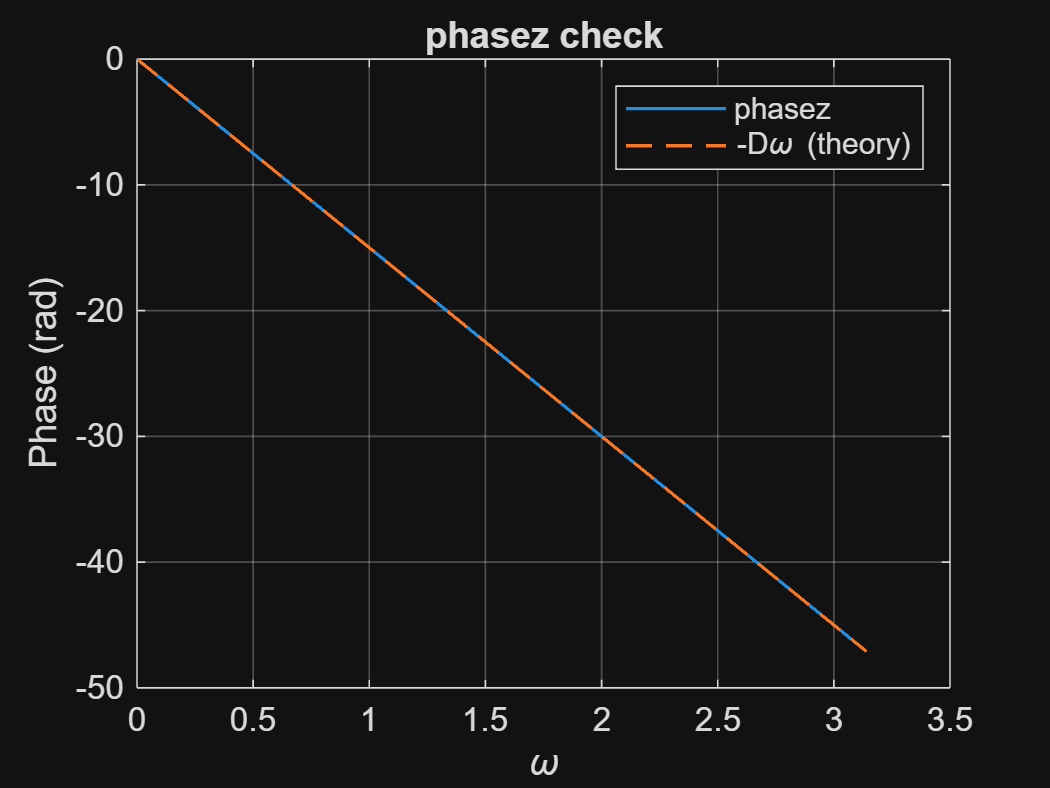

% phasez and theoretical line
figure;
plot(w_pz, phi_phasez, '-', w, phi_true, '--','LineWidth',1); grid on
xlabel('\omega'); ylabel('Phase (rad)')
legend('phasez','-D\omega (theory)')
title('phasez check')

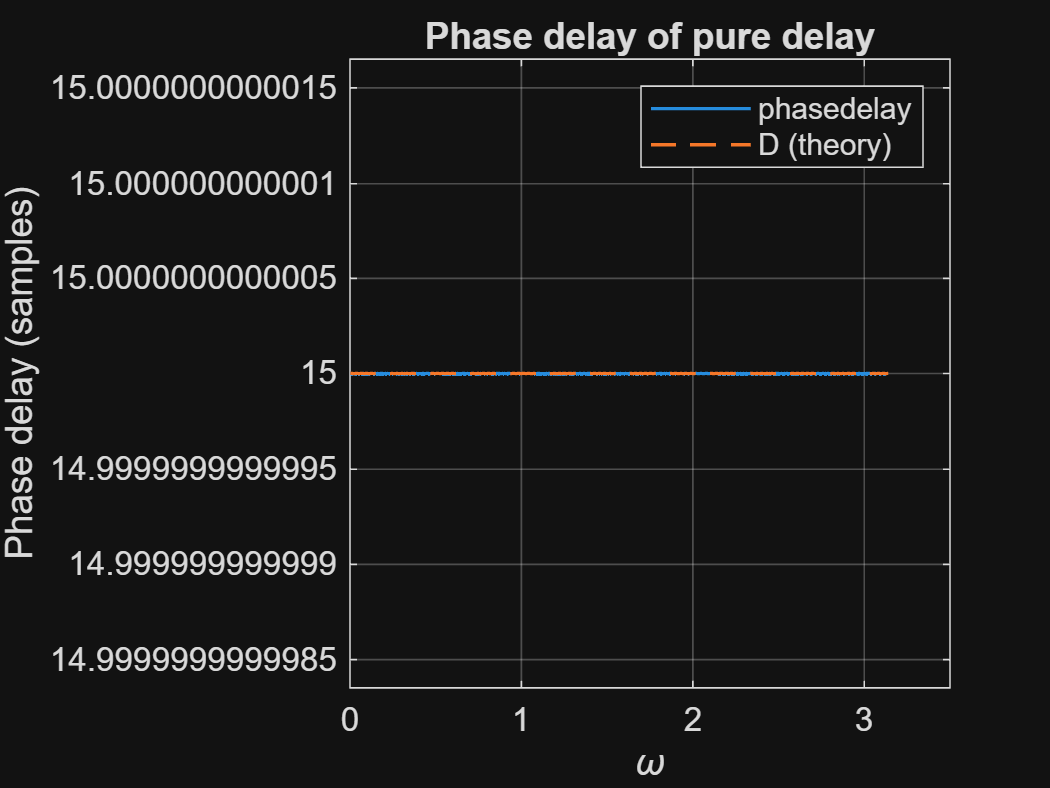

% Phase delay
figure;
plot(w_pd, tau_pd, '-', w, tau_true, '--','LineWidth',1); grid on
xlabel('\omega'); ylabel('Phase delay (samples)')
legend('phasedelay','D (theory)')
title('Phase delay of pure delay')

## Question 5.45

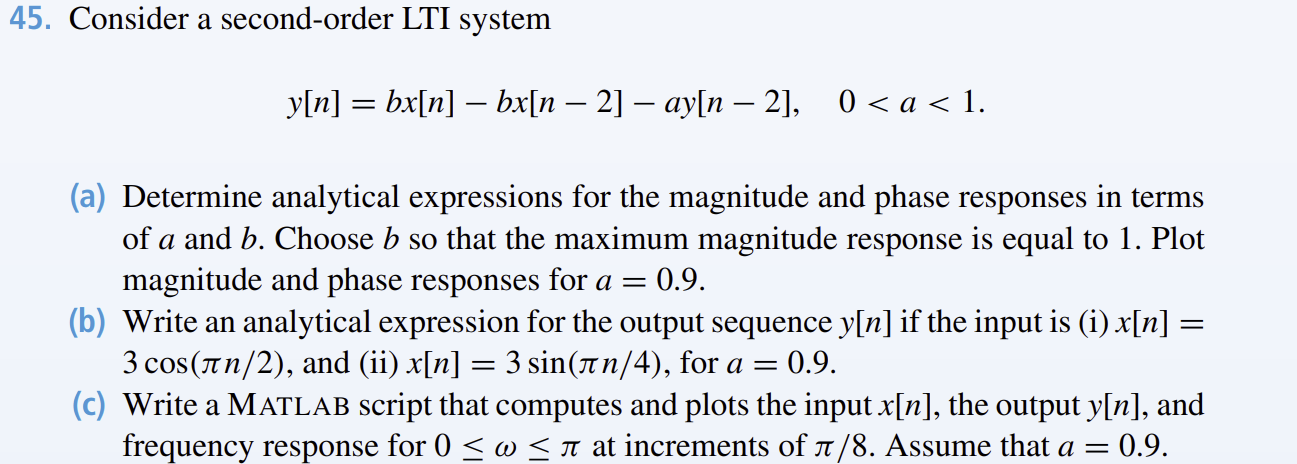

## Question 5.49

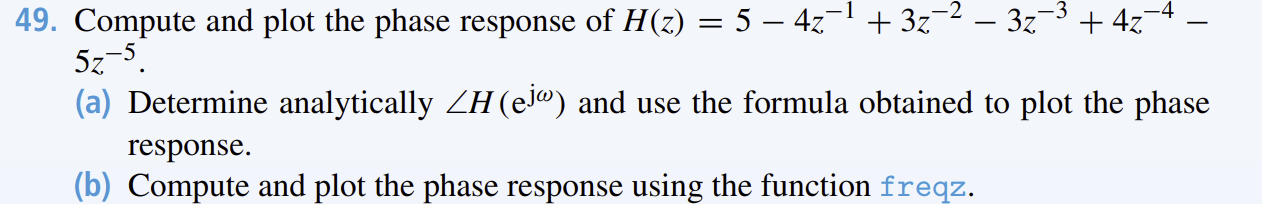

## Question 6.32

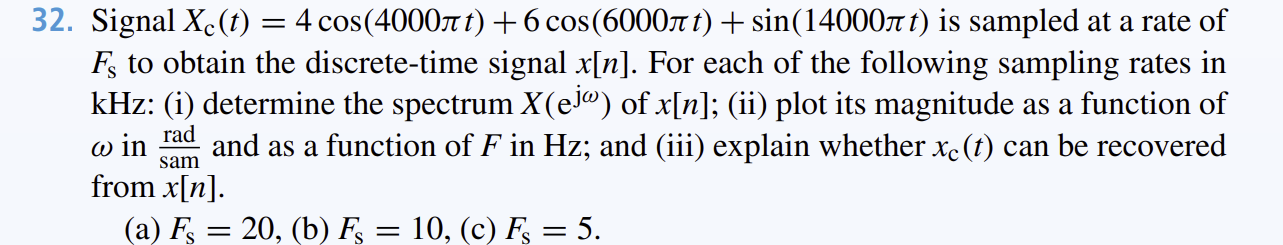

## Question 6.33

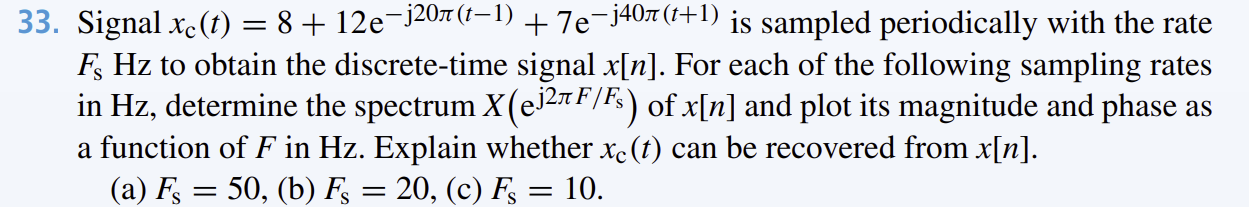

## Question 7.5 

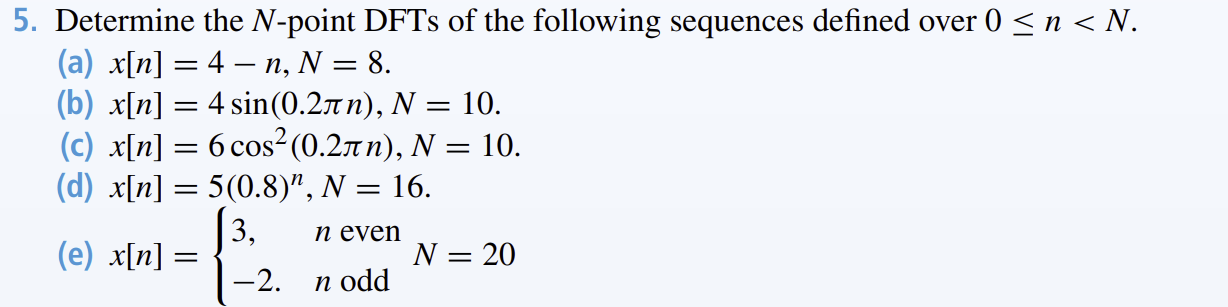

## Question 7.8

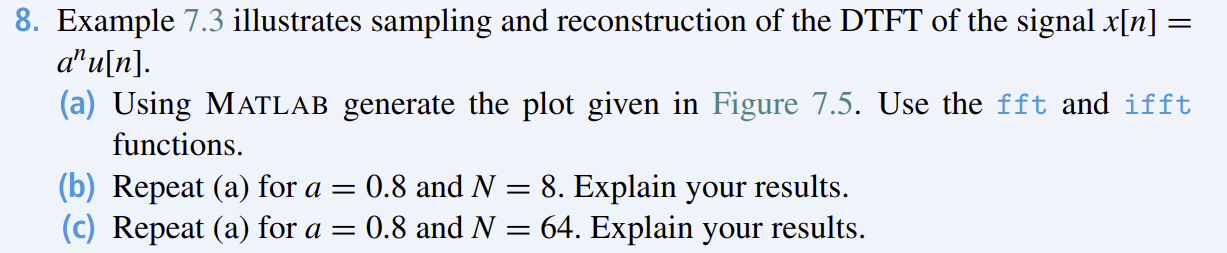

## Question 7.14

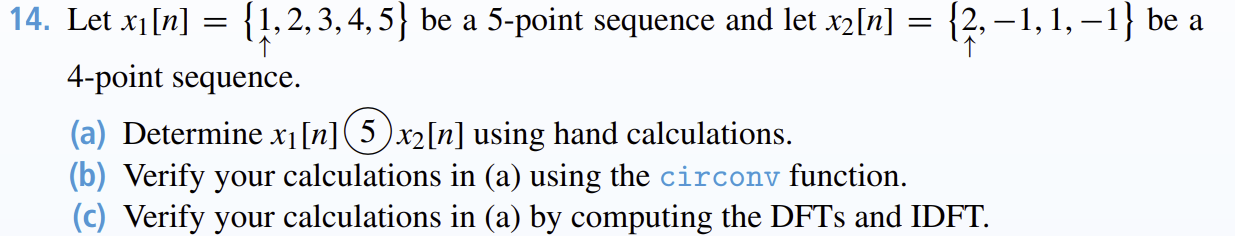

## Question 7.15

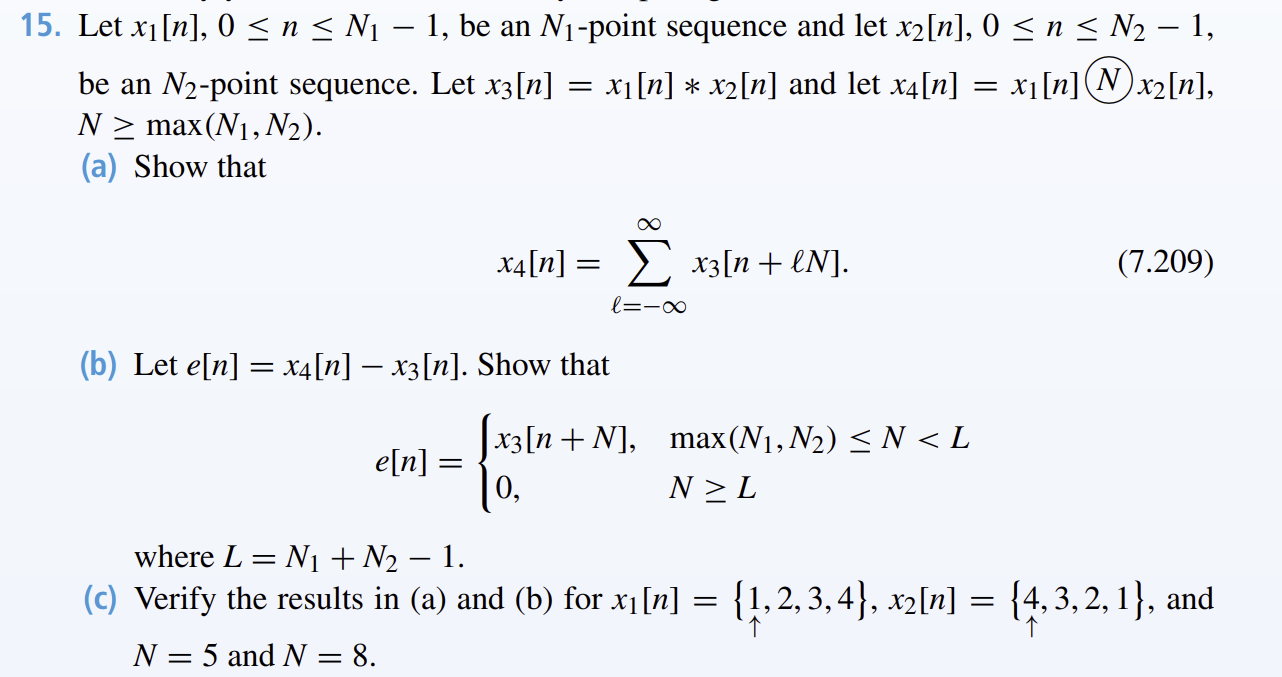

## Question 7.38